%% This script is used to read the binary file produced by the DCA1000
%% and Mmwave Studio
%% Command to run in Matlab GUI -
%readDCA1000('<ADC capture bin file>') function [retVal] = readDCA1000(fileName)
clear
%% global variables
% change based on sensor config
numADCSamples = 256; % number of ADC samples per chirp
numADCBits = 16; % number of ADC bits per sample
numRX = 4; % number of receivers
numLanes = 2; % do not change. number of lanes is always 2
isReal = 0; % set to 1 if real only data, 0 if complex data0
fileName = 'adc_datacollection_47.bin';

%% read file
% read .bin file
fid = fopen(fileName,'r');
adcData = fread(fid, 'int16');
% if 12 or 14 bits ADC per sample compensate for sign extension
if numADCBits ~= 16
    l_max = 2^(numADCBits-1)-1;
    adcData(adcData > l_max) = adcData(adcData > l_max) - 2^numADCBits;
end
fclose(fid);
fileSize = size(adcData, 1);
% real data reshape, filesize = numADCSamples*numChirps
if isReal
    numChirps = fileSize/numADCSamples/numRX;
    LVDS = zeros(1, fileSize);
    %create column for each chirp
    LVDS = reshape(adcData, numADCSamples*numRX, numChirps);
    %each row is data from one chirp
    LVDS = LVDS.';
   else
    % for complex data
    % filesize = 2 * numADCSamples*numChirps
    numChirps = fileSize/2/numADCSamples/numRX;
    LVDS = zeros(1, fileSize/2);
    %combine real and imaginary part into complex data
    %read in file: 2I is followed by 2Q
counter = 1;
for i=1:4:fileSize-1
    LVDS(1,counter) = adcData(i) + sqrt(-1)*adcData(i+2); LVDS(1,counter+1) = adcData(i+1)+sqrt(-1)*adcData(i+3); counter = counter + 2;
end
% create column for each chirp
LVDS = reshape(LVDS, numADCSamples*numRX, numChirps);
%each row is data from one chirp
LVDS = LVDS.';
end
%organize data per RX
adcData = zeros(numRX,numChirps*numADCSamples);
for row = 1:numRX
    for i = 1: numChirps

    adcData(row, (i-1)*numADCSamples+1:i*numADCSamples) = LVDS(i, (row-1)*numADCSamples+1:row*numADCSamples);

end
end
% return receiver data
retVal = adcData;
%adcData = adcData(1,1:end);

%this section averages data from each receiver


avgData = zeros(1,262144)

avgData =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


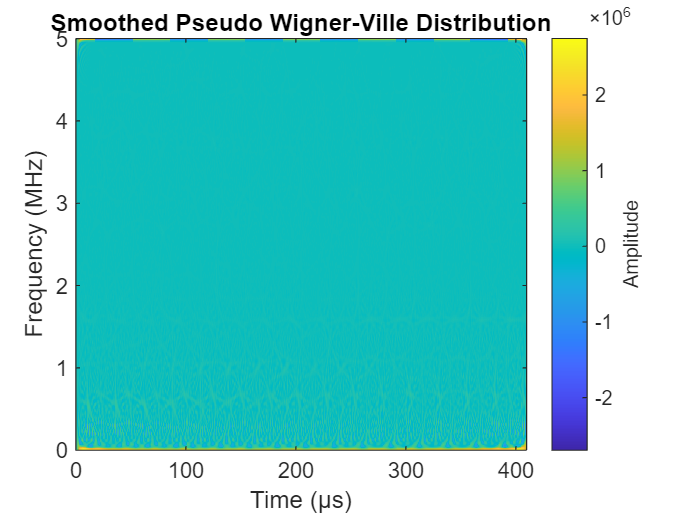

for i = 1:262144
    avgData(1,i) = adcData(1,i)+adcData(2,i)+adcData(3,i)+adcData(4,i);
end


   


%this section finds number of samples in 1/8th of a frame, to lower amount
%of points being processed
numCHframe = 128;  
numSAMPframe = numCHframe*numADCSamples;
numCH8thframe = numCHframe/8;
numSAMP8thframe = numCH8thframe*numADCSamples;


% current status 3/31: want to try on data file that contains collection of
% object moving while also creating a micro dop (walking while swinging
% arm, etc..) , need to read micro dop textbook to see methods used in that
% , values at very low frequencies can be seen possibly corresponding to a
% micro dop, this was done on something that wasn't moving, explainging why
% there is no "bias" frequency (the larger frequency that the micro doppler
% would be seen varying from, that is created by the movement of the object
% itself

%this section plots I and Q data to visualize time waveform and give expectation of what
%to see in freq over time plot 

% sampfreq = 10000e3;
% sampinterval = 1/sampfreq;
% 
% t = [0:1/10000e3:127*1/10000e3]
absavgData = abs(avgData);
% plot(t,real(avgData(1,1:128)),t,imag(avgData(1,1:128)))
% legend('I' , 'Q')
% 
% plot(t,absavgData(1,1:128))
% 
% totaltime = 262144/10000e3;

%cwt(absavgData(1,262144/4:3*(262144/4)),10000e3)

%computes Wigner-Ville distribution of magnitude of data, using the number
%of samples in an 8th of a frame, sampling rate of 10k, and the smoothed
%pseudo option 

wvd(abs(avgData(1,40*numSAMP8thframe:41*numSAMP8thframe)),10000e3,'smoothedPseudo')


%importing data from mike, will try smoothed pseudo wvd this time

%CANNOT USE IMPORTED DATA 04/01
%after computing CWT, clear that returned sampling freq from audioread does
%not correspond to adc sampling frequency, and therefor cannot get accurate
%plots from this data until that info is known

% [I, fsi] = audioread('[180501_10.48.21]_T02_radar_data_Opt0HRX1I.wav');
% [Q, fsq] = audioread('[180501_10.48.21]_T02_radar_data_Opt0HRX1Q.wav');
% X = abs(transpose(I + j*Q))

% 
% totaltime = length(I)/fsi;
% 
% samplesused = 4096;
% 
% %code for finding values greater than .1 in the data, as much of the data
% %sits at very close, small values
% 
% Y = X > .1
% 
% k = find(Y==1)
% 
% x = 2429653/4096

%wvd of imported, previous data

%wvd(X(1,593*samplesused:594*samplesused),fsi,'smoothedPseudo')



